clc
clear all

board_dim= 0.36; %board width/height (8squares x 4cm)
base_height = 0.15; %in meters
base_radius = 0.06; % (3squares = 12cm)/2
furthest = sqrt((board_dim +base_radius)^2 + 0.16^2);
shortest = 0.02 + base_radius; % inner frame = 2cm

## DH matrix

% syms a3 a4 d1 theta1 theta2 theta3 theta4;
% dhparams = [0 0 d1 theta1;
%             0 90 0 theta2;
%             a3 0 0 theta3;
%             q4 0 0 theta4];


## DH to Forward Kinematics

l1 = 15; % height (ground to second joint)
l2 = 27; % length of first arm
l3 = 23;% length of third arm
l4 = 10;% length of forth arm
q1 = 71.5651;
q2 = 51.3224;%[0,90]
q3 = 99.7;%[0,120]
q4 = 180-q2-q3;%[0,120]

a0 = 0;
a1 = 0;
a2=l2

a2 = 27

a3=l3

a3 = 23

aE=l4;
d1=l1

d1 = 15

d2 = 0;
d3 = 0;
d4 = 0;
dE = 0;
alpha0 = 0;
alpha1 = 90;
alpha2 = 0;
alpha3 = 0;
alphaE = 0;
theta1 = q1;
theta2 = 90-q2;
theta3 = -q3;
theta4 = -q4;
thetaE = 0;

Rx_10 = [1 0 0 0;
        0 cosd(alpha0) -sind(alpha0) 0;
        0 sind(alpha0) cosd(alpha0) 0;
        0 0 0 1];

Dx_10 = [1 0 0 a0;
        0 1 0 0;
        0 0 1 0;
        0 0 0 1];

Rz_10 = [cosd(theta1) -sind(theta1) 0 0;
        sind(theta1) cosd(theta1) 0 0;
        0 0 1 0
        0 0 0 1];

Dz_10 = [1 0 0 0;
        0 1 0 0;
        0 0 1 d1;
        0 0 0 1];

Rx_21 = [1 0 0 0;
        0 cosd(alpha1) -sind(alpha1) 0;
        0 sind(alpha1) cosd(alpha1) 0;
        0 0 0 1];
Dx_21 = [1 0 0 a1;
        0 1 0 0;
        0 0 1 0;
        0 0 0 1];

Rz_21 = [cosd(theta2) -sind(theta2) 0 0;
        sind(theta2) cosd(theta2) 0 0;
        0 0 1 0
        0 0 0 1];

Dz_21 = [1 0 0 0;
        0 1 0 0;
        0 0 1 d2;
        0 0 0 1];

Rx_32 = [1 0 0 0;
        0 cosd(alpha2) -sind(alpha2) 0;
        0 sind(alpha2) cosd(alpha2) 0;
        0 0 0 1];

Dx_32 = [1 0 0 a2;
        0 1 0 0;
        0 0 1 0;
        0 0 0 1];

Rz_32 = [cosd(theta3) -sind(theta3) 0 0;
        sind(theta3) cosd(theta3) 0 0;
        0 0 1 0
        0 0 0 1];

Dz_32 = [1 0 0 0;
        0 1 0 0;
        0 0 1 d3;
        0 0 0 1];

Rx_43 = [1 0 0 0;
        0 cosd(alpha3) -sind(alpha3) 0;
        0 sind(alpha3) cosd(alpha3) 0;
        0 0 0 1];

Dx_43 = [1 0 0 a3;
        0 1 0 0;
        0 0 1 0;
        0 0 0 1];

Rz_43 = [cosd(theta4) -sind(theta4) 0 0;
        sind(theta4) cosd(theta4) 0 0;
        0 0 1 0
        0 0 0 1];

Dz_43 = [1 0 0 0;
        0 1 0 0;
        0 0 1 d4;
        0 0 0 1];

Rx_E4 = [1 0 0 0;
        0 cosd(alphaE) -sind(alphaE) 0;
        0 sind(alphaE) cosd(alphaE) 0;
        0 0 0 1];

Dx_E4 = [1 0 0 aE;
        0 1 0 0;
        0 0 1 0;
        0 0 0 1];

Rz_E4 = [cosd(thetaE) -sind(thetaE) 0 0;
        sind(thetaE) cosd(thetaE) 0 0;
        0 0 1 0
        0 0 0 1];

Dz_E4 = [1 0 0 0;
        0 1 0 0;
        0 0 1 dE;
        0 0 0 1];

T_10 = Dx_10 * Rx_10 * Dz_10 * Rz_10;
T_21 = Dx_21 * Rx_21 * Dz_21 * Rz_21;
T_32 = Dx_32 * Rx_32 * Dz_32 * Rz_32;
T_43 = Dx_43 * Rx_43 * Dz_43 * Rz_43;
T_E4 = Dx_E4 * Rx_E4 * Dz_E4 * Rz_E4;

T_E0 = T_10 * T_21 * T_32 * T_43 * T_E4;
original = [0;0;0;1];
step1 = original;
step2 = T_10*original;
step3 = T_10*T_21*original;
step4 = T_10 * T_21 * T_32 * original;
step5 = T_10 * T_21 * T_32 * T_43 * original;
step6 = T_E0* original;
graph = [step1,step2,step3,step4,step5,step6]

graph =          0         0         0    6.6655   10.1891   10.1891
         0         0         0   19.9966   30.5675   30.5675
         0   15.0000   15.0000   31.8733   11.7527    1.7527
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


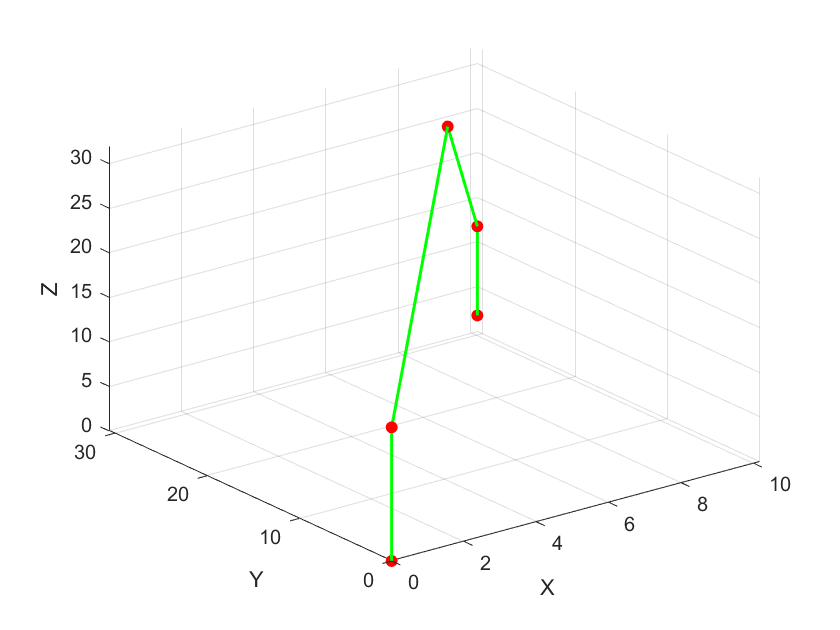

plot3(graph(1,:),graph(2,:),graph(3,:),'g','LineWidth',1.5)
hold on 
scatter3(graph(1,:),graph(2,:),graph(3,:),'red','filled')
xlabel('X')
ylabel('Y')
zlabel('Z')

grid on
hold off

% plotTransforms([1,1,1],T_10)

## solution manifold 2d sketch

Q1 = linspace(-pi/2,pi/2,100); 
Q2 = linspace(0,pi/2,100);
Q3 = linspace(0,deg2rad(170),100); % joint can't be folded into itself
%Q4=linspace(-pi/2,pi/2,50);

h=6+l4; % expected height of the chess pieces
E=10^(-8);
n1=length(Q1);
n2=length(Q2);
n3=length(Q3);
%n4=length(Q4);
s=1;
lmax=0

lmax = 0

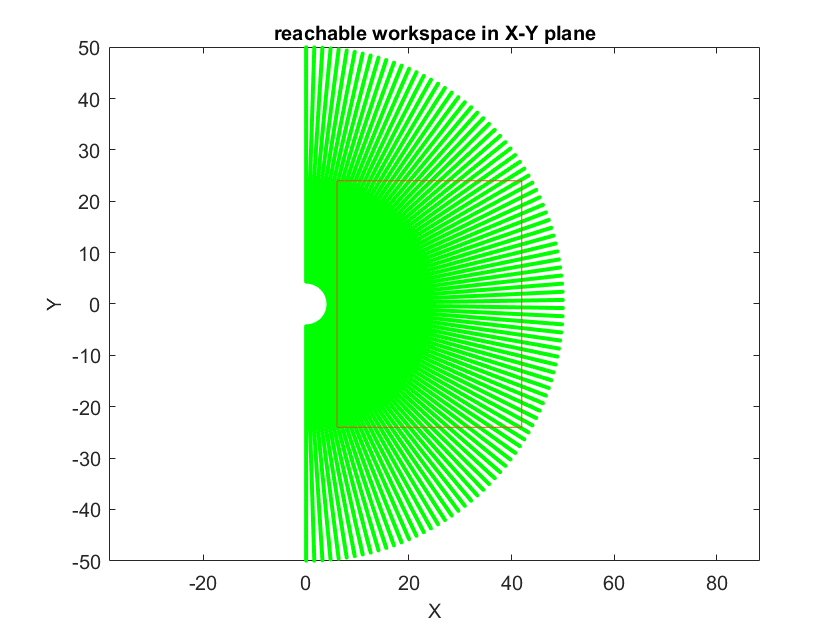

for i=1:1:n1
    for j=1:1:n2
        for k=1:1:n3
            %for m=1:1:n4
                L=l2*sin(Q2(j))+l3*cos(Q3(k)+Q2(j)-pi/2); 
                H=l1-(l2*cos(pi-Q2(j))+l3*sin(Q3(k)+Q2(j)-pi/2));
               %L=l2*sin(Q2(j))+l3*cos(Q3(k)+Q2(j)-pi/2)+l4*cos(Q4(m)+Q3(k)+Q2(j)-pi/2); 
               %H=l1-(l2*cos(pi-Q2(j))+l3*sin(Q3(k)+Q2(j)-pi/2)+l4*sin(Q4(m)+Q3(k)+Q2(j)-pi/2));
               x = L*cos(Q1(i)); % compute x coordinates
               y = L*sin(Q1(i));
               if (H-h)<E X(s)=x;Y(s)=y;s=s+1;
               end
               if L>lmax lmax=L;
              
               %end
            end
        end
    end
end

%2(frame) + 32(8x4cm squares) + 2(frame) = 36 + space

plot(X,Y,'g.')
hold on
plot([6,6,6+36,6+36,6],[24,-24,-24,24,24])
hold off
axis equal;
  xlabel('X','fontsize',10)
  ylabel('Y','fontsize',10)
  title('reachable workspace in X-Y plane','fontsize',10) 

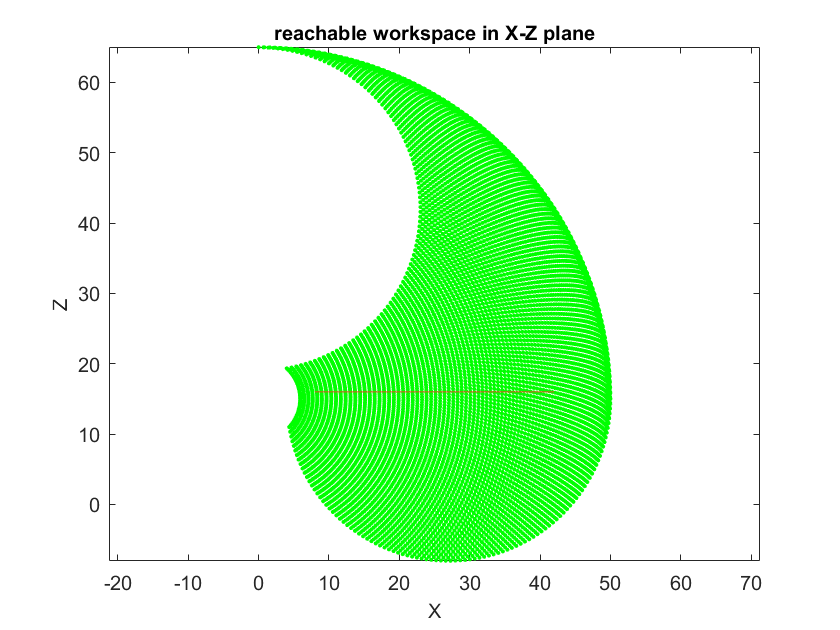

s=1; 
for j=1:1:n2
        for k=1:1:n3
            %for m=1:1:n4
                X2(s)=l2*sin(Q2(j))+l3*cos(Q3(k)+Q2(j)-pi/2);
                Z(s)=l1-(l2*cos(pi-Q2(j))+l3*sin(Q3(k)+Q2(j)-pi/2));
               %X2(s)=l2*sin(Q2(j))+l3*cos(Q3(k)+Q2(j)-pi/2)+l4*cos(Q4(m)+Q3(k)+Q2(j)-pi/2); 
               %Z(s)=l1-(l2*cos(pi-Q2(j))+l3*sin(Q3(k)+Q2(j)-pi/2)+l4*sin(Q4(m)+Q3(k)+Q2(j)-pi/2));
               s=s+1;
            %end
            end
        end
       
        
plot(X2,Z,'g.')
axis equal;
  xlabel('X','fontsize',10)
  ylabel('Z','fontsize',10)
  title('reachable workspace in X-Z plane','fontsize',10)
hold on
plot([6+2,6+36],[h,h]) %6+2 = base radius + outer frame of chess board, 36cm includes outer frame (2cm) -> x2 (32 + 2x2)
hold off

%%Inverse Dynamics
x=step6(1);
y=step6(2);
z=step6(3);
%x=8
%y=24
%z=1

a=sqrt(x^2+y^2);
m=-1/a*(-l1+z+l4)

m = 0.1008

n=(l2^2-l3^2+(l4)^2-(z-l1)^2-a^2)/2/a

n = -14.1784

p=2*(m*n-l4)/(m^2+1);
q=((n)^2+l4^2-l3^2)/(m^2+1)

q = -225.6814

r1=(-p+sqrt(p^2-4*q))/2

r1 = 30.1206

%r2=(-p-sqrt(p^2-4*q))/2
s1=m*r1+n

s1 = -11.1428

%s2=m*r2+n
Theta2_1=atand((a+s1)/(r1-l1+z))

Theta2_1 = 51.3224

if Theta2_1<0 Theta2_1=Theta2_1+180
end
%Theta2_2=atand((a+s2)/(r2-l1+z))
Theta4_1=atand(-s1/(r1-l4))

Theta4_1 = 28.9776

if Theta4_1<0 Theta4_1=Theta4_1+180
end

%Theta_4_2=atand(-s2/(r2-l4))
Theta3_1=180-Theta4_1-Theta2_1

Theta3_1 = 99.7000


%Theta3_2=180-Theta4_2-Theta2_2
Theta1=atand(y/x)

Theta1 = 71.5651